`SW and Methods for Statistical Analysis`

# **Time Series Analysis of Nvidia Stock Returns (2012-2024) - The Univariate Case**

In this MATLAB Livebook, a comprehensive Univariate Time Series Analysis will be carried out to study the stock prices and returns of the most capitalized (as of June 24th) company of the world, Nvidia Corporation (**NASDAQ: NVDA**).

This livebook, the data and supplemental materials will be available on this [Github Repository](https://github.com/trarez/EsameSoftware).

The livebook will mainly have a mix of statistical and financial notions and concepts. Technical and non-intuitive aspects of the scripts will be explained in the cells with "%%".

*Where do I gather information for this project? *Main Resources:

- [Analysis of Financial Time Series](https://www.wiley.com/en-ca/Analysis+of+Financial+Time+Series%2C+3rd+Edition-p-9780470414354) by Ruey S. Tsay (main resource and guideline;

- [Time Series Analysis with Applications in R](https://link.springer.com/book/10.1007/978-0-387-75959-3) by Jonathan D. Cryer and Kung-Sik Chan;

- [Forecasting: Principles and Practices](https://otexts.com/fpp3/) by Rob J. Hyndman and George Athanasopoulos;

- [Introductory Econometrics: A Modern Approach](https://books.google.es/books/about/Introductory_Econometrics.html?id=4TZnpwAACAAJ&redir_esc=y) by Jeffrey Wooldridge;

- [Time Series Analysis: Forecasting and Control, 5th Edition](https://www.wiley.com/en-us/Time+Series+Analysis%3A+Forecasting+and+Control%2C+5th+Edition-p-9781118675021) by George E. P. Box, Gwilym M. Jenkins, Gregory C. Reinsel, Greta M. Ljung;

- Professor's slides;

- Other slides and papers: [Non-stationarity Time Series and Unit Root Tests](https://web.archive.org/web/20161130133316/http://www.econ.ku.dk/metrics/Econometrics2_05_II/Slides/08_unitroottests_2pp.pdf) by H. B. Nielsen (click on the link to download), [Structural Breaks in Time Series](https://onlinelibrary.wiley.com/doi/epdf/10.1111/j.1467-9892.2012.00819.x?saml_referrer) by A. Aue, L. Horvàth (access through Institutional account), [A new look at the statistical model identification](https://ieeexplore.ieee.org/document/1100705) by H. Akaike, Change points and structural breaks by K. Kotzé,  [Empirical properties of asset returns: stylized facts and statistical issues](http://rama.cont.perso.math.cnrs.fr/pdf/empirical.pdf&ved=2ahUKEwiQ0b_124-HAxWCBdsEHUFWAq0QFnoECBQQAQ&usg=AOvVaw0IDWmYos3PJJp1fONBthuQ) by R. Cont (click on the link to download), [A practical guide to volatility forecasting through calm and storm](https://www.google.com/url?sa=t&source=web&rct=j&opi=89978449&url=https://www.sas.upenn.edu/~fdiebold/papers/misc/Brownlees.pdf&ved=2ahUKEwjniefPsa6HAxW7UKQEHSJmDiwQFnoECBMQAQ&usg=AOvVaw2O0V0rx7KV72d_EP7jIEQp) by C. Brownlees, R. Engle, B. Kelly (click on the link to download), [Testing for Unit Roots: What Should Students Be Taught?](https://www.jstor.org/stable/1183489) by P. E. Kennedy, J. Elder.

- MATLAB Tutorials, [Introduction to volatility models with MATLAB (ARCH, GARCH, GJR-GARCH)](https://mmquant.net/introduction-to-volatility-models-with-matlab-garch/) by mmquant.

- Investopedia;

- Youtube Tutorials: [Economic Time Series Modelling in MATLAB](https://www.youtube.com/watch?v=UCChM5Mul_E); [Power Comparison of Normality Tests](https://www.youtube.com/watch?v=ioJD3RTUUXE);

- English Wikipedia (with a grain of salt);

- ... and a bit of Gemini LLM (with two grains of salt!).

## Data Importing and Descriptive Statistics

The data have been downloaded at June 24th on Yahoo! Finance and imported on Github for easier accessibility.

df = readtable("https://raw.githubusercontent.com/trarez/EsameSoftware/main/Nvidia%20Stock%20Prices.csv","VariableNamingRule","preserve")

df = 2915×7 table
       Date        Open       High        Low       Close     Adj Close      Volume  
    __________    _______    _______    _______    _______    _________    __________

    2012-11-20     0.2895    0.29075    0.28425    0.28725     0.26517     3.3698e+08
    2012-11-21    0.28725    0.29625      0.287     0.2955     0.27279     4.2231e+08
    2012-11-23    0.29675      0.301    0.29525     0.2975     0.27464     2.7693e+08
    2012-11-26      0.298     0.3035     0.2975    0.30275     0.27948      3.646e+08
    2012-11-27     0.3015     0.3085      0.299      0.304     0.28064      4.514e+08
    2012-11-28    0.30275      0.308      0.299     0.3065     0.28294     3.9833e+08
    2012-11-29      0.307     0.3085        0.3      0.

rng(0, "twister") % for eventual reproducibility

During a trading day, the stock prices vary. Yahoo! Finance provide basic intra-day distributional values. With these it might be possible to deepen the analysis (for example, by building *candlesticks *on a time series*, *figure below), but for now let's just consider **adjusted close** prices.

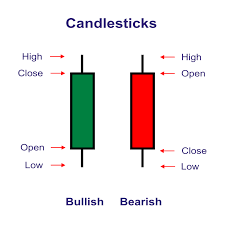

The closing price is the raw price, which is just the cash value of the last transacted price before the market closes. The adjusted closing price factors in anything that might affect the stock price after the market closes, for example dividend payments to shareholders, as shown in the formula below (*dividends factoring*) (Source:[ *Investopedia*](https://www.investopedia.com/terms/a/adjusted_closing_price.asp)*).*:


$$R_t = \frac{P_t + D_t}{P_{t-1}} - 1$$


df = df(:, {'Date', 'Adj Close'});
dates = df.Date;
prices = df.("Adj Close");

It's important to keep in mind that trading days differ from actual days, because during the weekend and holidays the stock market is closed.

There are some strategies to deal with this:

- leave the data as they are: technically no information is lost, because no trading occurs;

- missing data imputation.

We will leave the data as they are, without imputation.

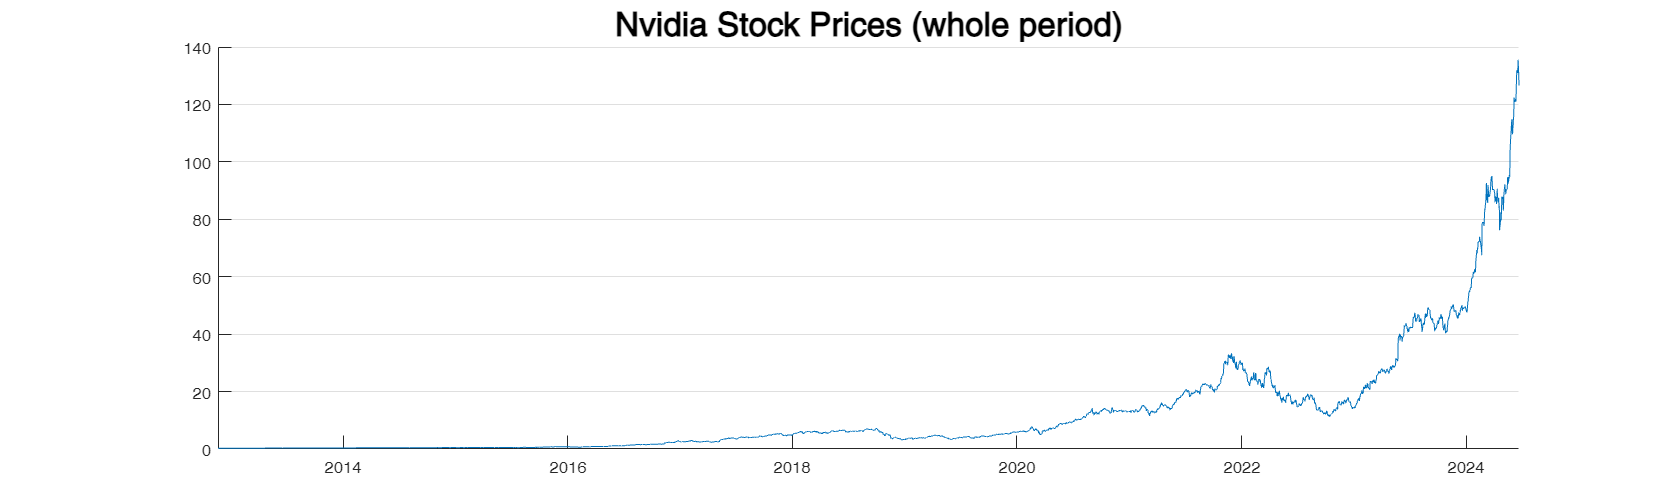

figure(); % Always use "figure" when a plotting, I didn't use it before and it was very buggy
plot(dates, prices);
title("Nvidia Stock Prices (whole period)", "FontSize",20);
set(gca, "XGrid", "off", "YGrid", "on");
set(gcf, 'position', [10, 10, 2000, 600]);
box off

The time series is splitted in half and the visualization is performed on two different plots, in order to better understand the price levels before January 2016.

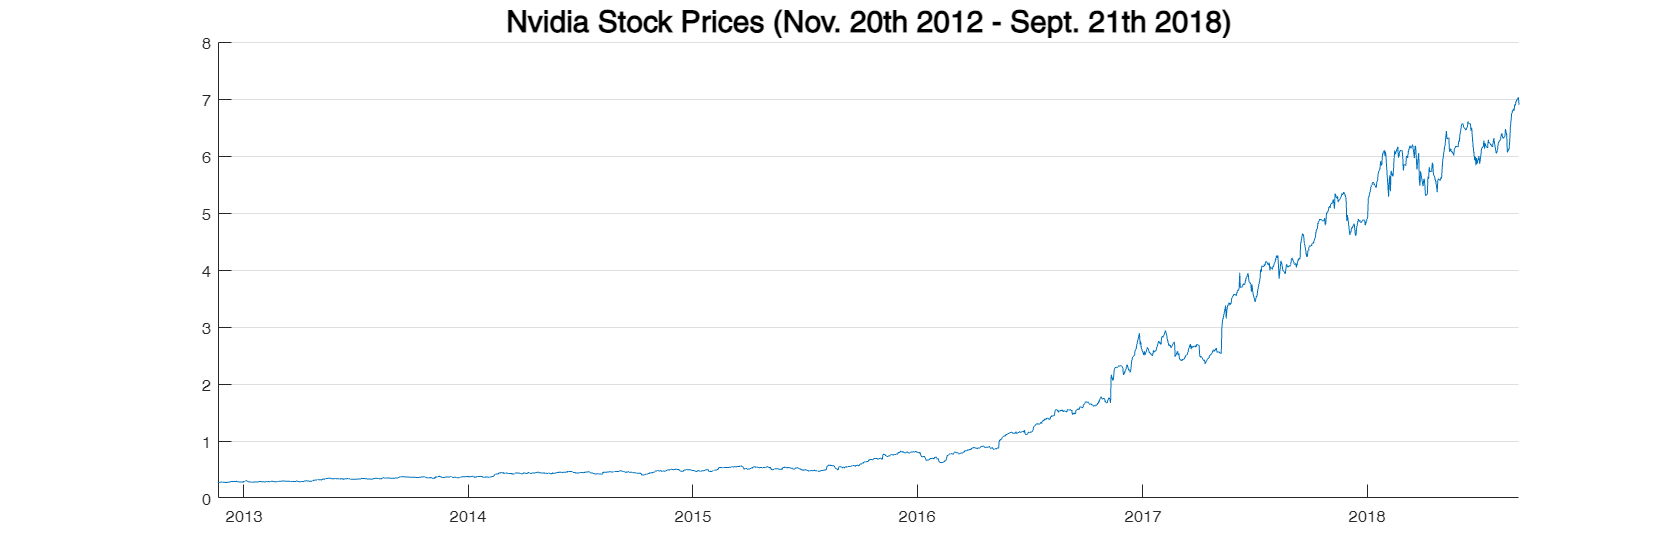

figure();
middleDay = round(length(prices)/2);
plot(dates(1:middleDay) , prices(1:middleDay));
title("Nvidia Stock Prices (Nov. 20th 2012 - Sept. 21th 2018)", "FontSize", 18);
set(gca, "XGrid", "off", "YGrid", "on");
set(gcf, 'position', [10, 10, 1800, 600]);
box off

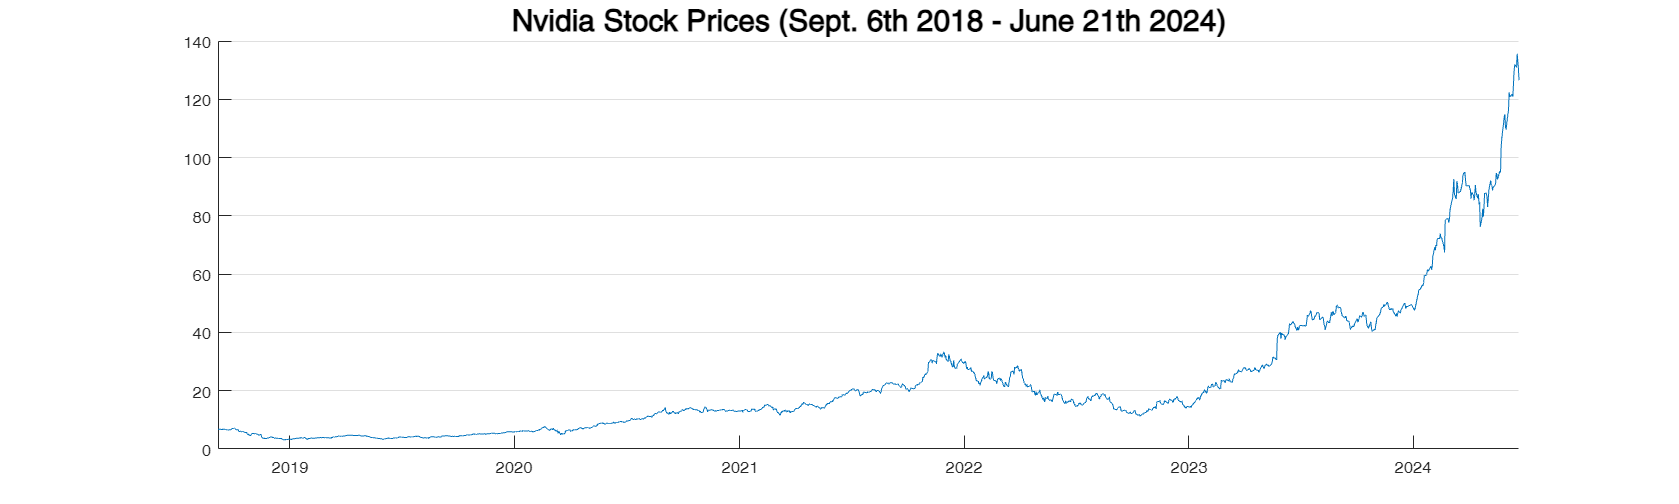

middleDayNext = round(length(prices)/2) + 1;

plot(dates(middleDayNext:end) , prices(middleDayNext:end));
title("Nvidia Stock Prices (Sept. 6th 2018 - June 21th 2024)", "FontSize", 18);
set(gca, "XGrid", "off", "YGrid", "on");
set(gcf, 'position', [10, 10, 2000, 600]);
box off

Given the quasi-exponential nature of the time series (especially in the second half), the series can be plotted in a logarithmic scale.

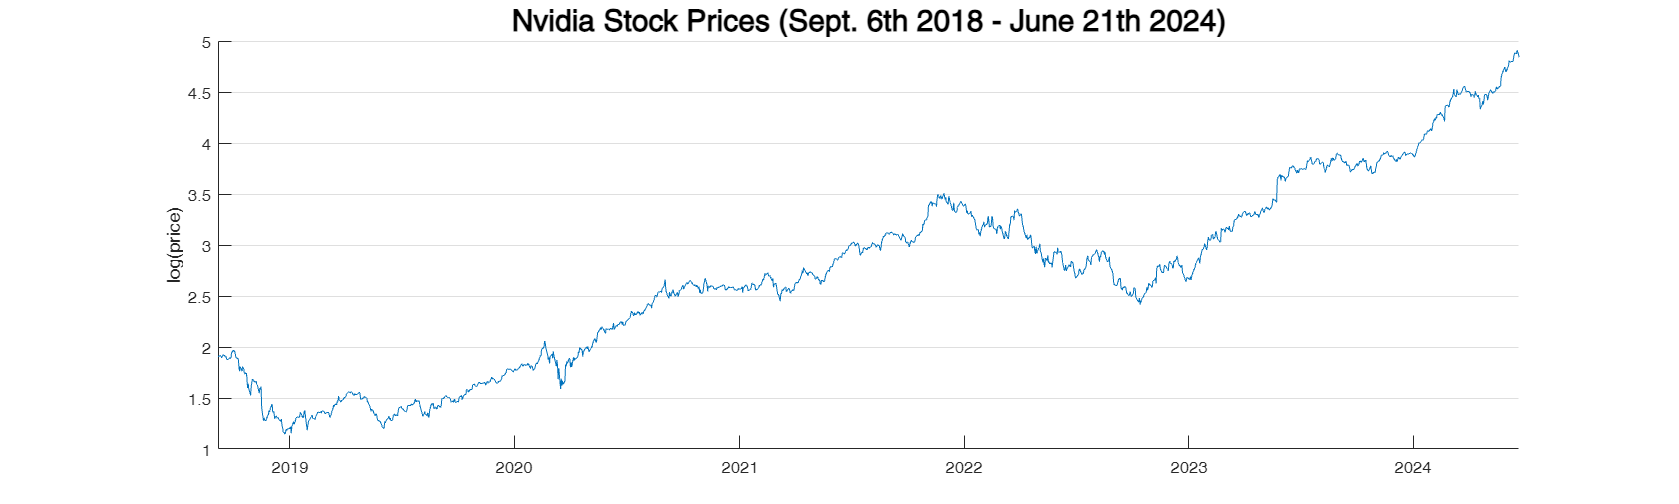

plot(dates(middleDayNext:end) , log(prices(middleDayNext:end)));
title("Nvidia Stock Prices (Sept. 6th 2018 - June 21th 2024)", "FontSize", 18);
set(gca, "XGrid", "off", "YGrid", "on");
ylabel("log(price)");
set(gcf, 'position', [10, 10, 2000, 600]);
box off

What interests the most to analysts and investors are not prices per se, but the stock **returns **(daily, monthly, yearly, ...).

Campbell, Lo and MacKinlay (1997) give two main reasons for using returns:

- "for average investors, return of an asset is a complete and scale-free summary of the investment opportunity"; 

- "return series are easier to handle than price series because the former have more attractive statistical properties".

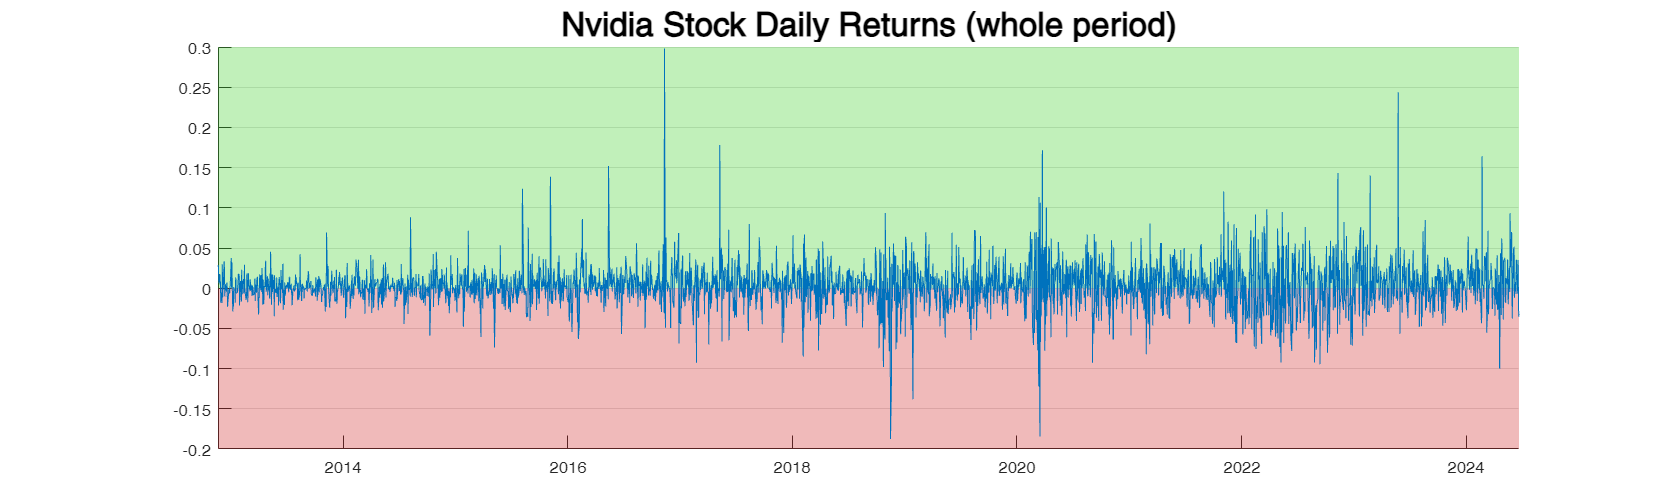

returns = tick2ret(prices); % function that converts price levels to return. Differencing causes the first observation to be lost.
figure();
hold on;
patch([dates(1), dates(end), dates(end), dates(1)], [0.3, 0.3, 0, 0], [0.2, 0.8, 0.1], "FaceAlpha", 0.3, "EdgeColor", "none")
patch([dates(1), dates(end), dates(end), dates(1)], [0, 0, -0.2, -0.2], [0.8, 0.1, 0.1], "FaceAlpha", 0.3, "EdgeColor", "none")
plot(dates(2:end), returns)
title("Nvidia Stock Daily Returns (whole period)", "FontSize", 20);
set(gca, "XGrid", "off", "YGrid", "on");
set(gcf, 'position', [10, 10, 2000, 600]);
hold off;

This is the main time series of interest and inquiry. From here we can understand an essential phenomenon of financial markets, **volatility**, a process concerned with the evolution of conditional variance of the return over time. Interesting periods of volatility may be highlighted to analyze the phenomenon with proper models (GARCH and its broad range of extensions, Implied Volatility Estimation and so forth). More of that later in the Volatility Analysis section.

### Before going further: *gross *or *log-returns?*

The first important analyst decision (*forking path*) when it comes to analyzing financial data is to choose between *gross *or *log returns*.

Log returns have more tractable statistical and mathematical properties. These are preferred for financial time series analysis, especially because the sample may more probably resemble a normal distribution (absolute higher values tend to be shrunk the most, less *fat-tailedness*) with a stable variance.

We will consider %logreturns for numerical stability.

logreturns = log(1 + returns) * 100;

The logarithmic function is a monotonic transformation, hence only values magnitude change a bit, as shown below:

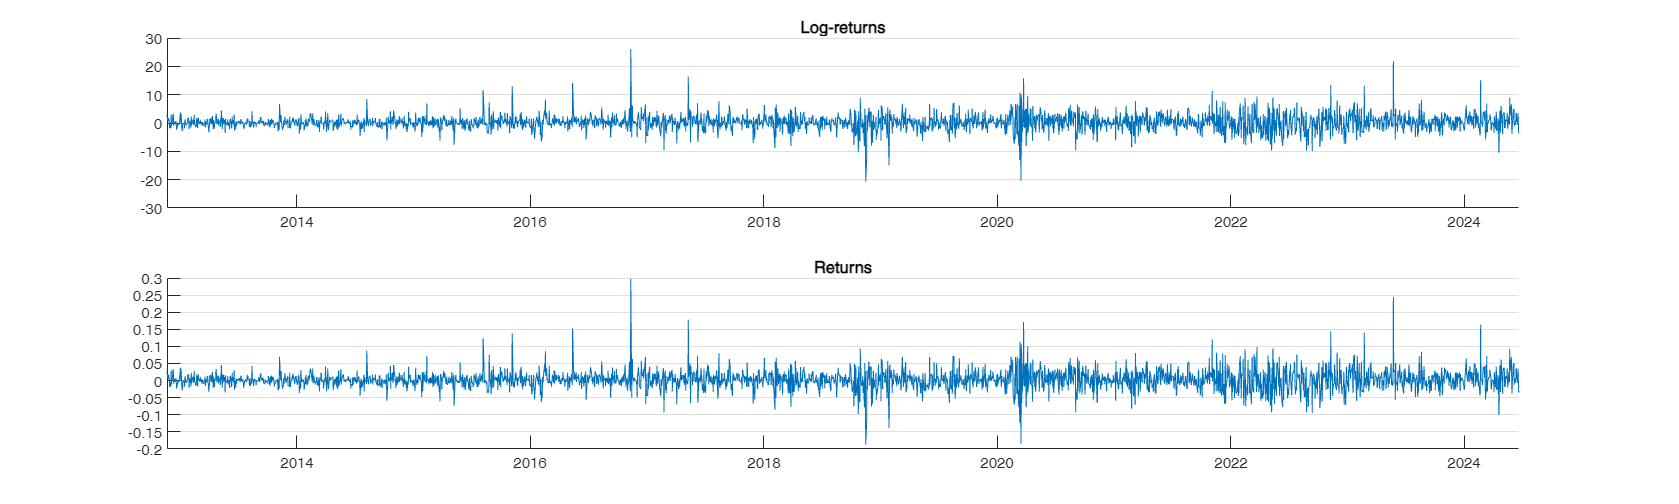

tiledlayout(2,1);
% Tile 1
nexttile
plot(dates(2:end), logreturns);
set(gca, "XGrid", "off", "YGrid", "on");
title("Log-returns");
box off;

%tile 2
nexttile
plot(dates(2:end), returns);
set(gca, "XGrid", "off", "YGrid", "on");
title("Returns");
box off;

For a better tractation on log transformations in economic and financial time series, read [*The Role of the Log Transformation in Forecasting Economic Variables*](https://papers.ssrn.com/sol3/papers.cfm?abstract_id=1368131) by *Helmut Lütkepohl* and *Fang Xu.*

*TL:DR: "For a range of economic variables substantial forecasting improvements from taking logs are found if the log transformation actually stabilizes the variance of the underlying series. Using logs can be*

*damaging for the forecast precision if a stable variance is not achieved."*

Parts of the analysis will be made both with simple and log-returns, in order to better understand the distributional differences, statistical properties and results.

### Descriptive Plots and Moments estimation

A common feature of most asset daily returns distributions is their ***fat-tailedness. ***This *fat-tailedness, *quantified by (excess) **kurtosis **(the 4th distribution moment), means that there is a higher probability of extreme events (returns much higher or lower than the average value) that fall outside 2-3 standard deviations (2-3σ) from the mean with respect to the normal distribution. This is one of the reason why assuming the normal distribution for either log-returns and simple returns is limited, other than the fact that simple returns are lower-bounded to -1, while the normal distribution to $-\infty$. Another reason is due to the **skewness **(3rd moment), where the distribution is not symmetrical around the mean.

Given a sufficient number of observations, it is possible to build the empirical distribution curve with both **Kernel Density Smoothing **and **histograms**. Both the KDE (continuous) and histogram (discrete) are *non-parametric *estimations of the theoretical PDF.

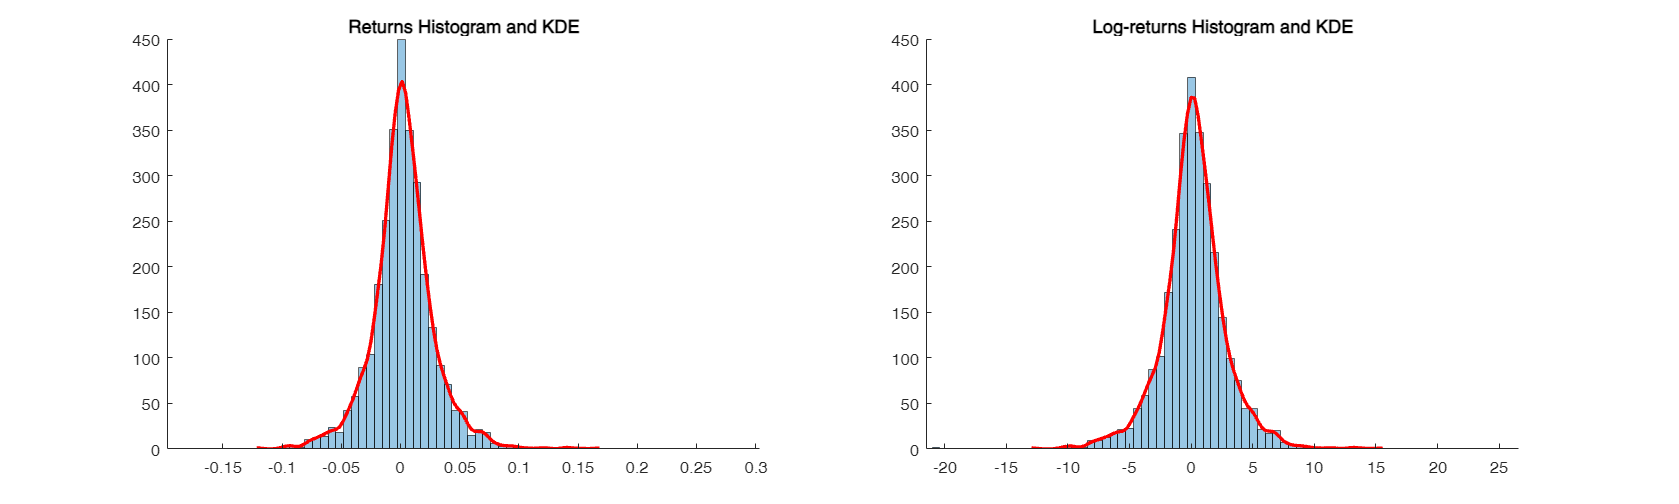

tiledlayout(1,2);

% Tile 1
ah1 = nexttile;
h1 = histfit(returns, 75, "kernel");
%% The "histfit" function belongs to the Statistics and Machine Learning Toolbox. It permits to simultaneously create a histogram and fit a kde, if specified. 
%% Distributions may be fitted (parametric).

%% histfit outputs a composite object, made of the kde curve and the histogram. These are called handles.
h1(1).FaceAlpha = 0.4; h1(1).EdgeAlpha = 0.6; %% Handle for histogram
h1(2).Color = "Red"; %% Handle for KDE curve
box off
title(ah1, "Returns Histogram and KDE")


% Tile 2
temp1 = nexttile;
h2 = histfit(logreturns, 75, "kernel");
%% The "histfit" function belongs to the Statistics and Machine Learning Toolbox. It permits to simultaneously create a histogram and fit a kde, if specified. 
%% Distributions may be fitted (parametric).

%% histfit outputs a composite object, made of the kde curve and the histogram. These are called handles.
h2(1).FaceAlpha = 0.4; h2(1).EdgeAlpha = 0.6; %% Handle for histogram
h2(2).Color = "Red"; %% Handle for KDE curve
title(temp1, "Log-returns Histogram and KDE")
box off

At first glance, the KDE curves recall a *leptokurtic normal distribution.*

Another common graphical method is the **Q-Q plot**, as it compares the sample quantiles to a specific distribution quantiles. It can also be used to compare two samples, to see whether they come from the same distribution.

For now let's use it to compare our sample with the normal distribution:

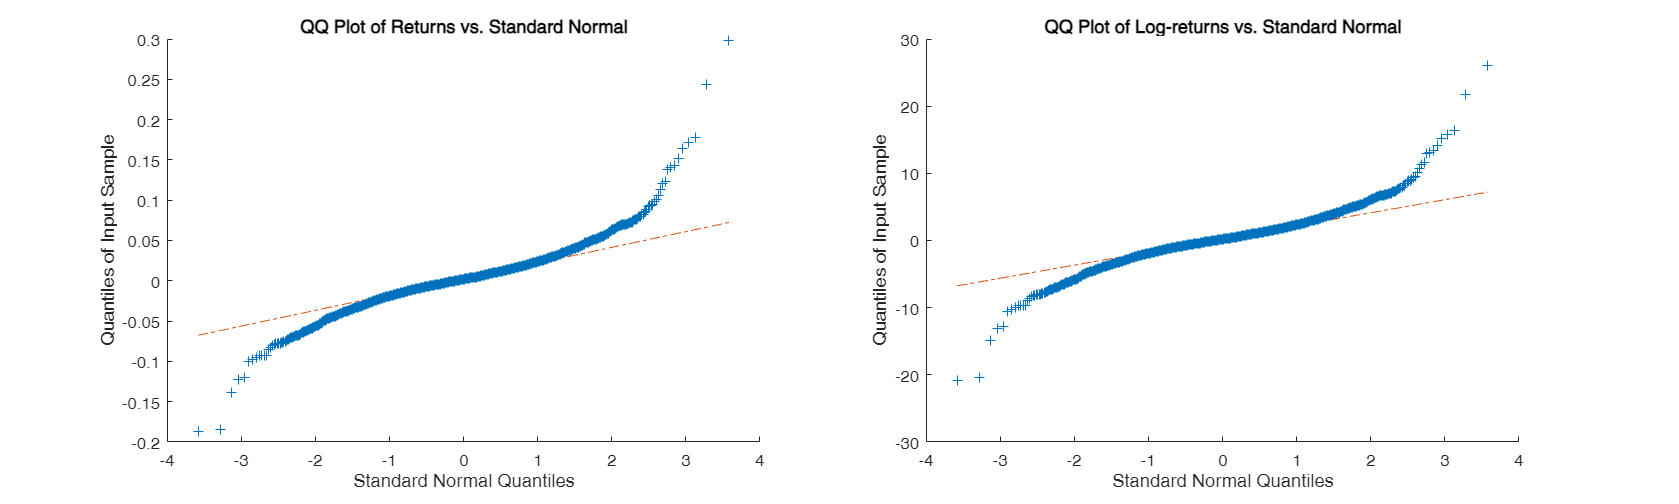

tiledlayout(1,2);

temp1 = nexttile;
qqplot(returns); %% the default hypothesized distribution is the normal one. Others can be considered.
title(temp1, "QQ Plot of Returns vs. Standard Normal")

temp2 = nexttile;
qqplot(logreturns);
title(temp2, "QQ Plot of Log-returns vs. Standard Normal")

The S-shaped data means the sample have "more extreme values" than the normal distribution. As expected, the log-returns sample tails are closer to the identity line, but not by much.

These basic descriptive tools shows why **Extreme Value Theory **is an important field of quantitative finance, especially for *risk management *(hedging strategies) and option pricing.

### Sample moments calculations

Function for estimating the first four moments (i.e., mean, variance, skewness, kurtosis) are coded:

1. Sample mean: $\hat{\mu} = \frac{1}{T}\sum^T_{t=1}x_t$

% tbh, very unnecessary to create these UDF (User-defined functions), just
% did them to practice with MATLAB

function myMean = calculateMean(sample)

The simple returns mean is: 0.00251


The log-returns mean is: 0.21167


  if ~isvector(sample) && ~ismatrix(sample) %& the ~ means "everything excluded"
    error('Input must be a vector or matrix of numbers.');
  end

  if ~isempty(sample)  % Avoid division by zero for empty arrays
    myMean = sum(sample) / length(sample);
  else
    myMean = NaN;  % Return NaN for empty arrays
  end
end

fprintf("The simple returns mean is: %.5f\n", calculateMean(returns));
fprintf("The log-returns mean is: %.5f\n", calculateMean(logreturns));

2. Sample variance:

function myVar = calculateVar(sample)

The simple returns variance is: 0.00080


The log-returns variance is: 7.85272


  biasCorr = 1/(length(sample) - 1);
  if ~isvector(sample) && ~ismatrix(sample) %& the ~ means "everything excluded"
    error('Input must be a vector or matrix of numbers.');
  end
  if ~isempty(sample)  % Avoid division by zero for empty arrays
    myVar = biasCorr * sum((sample - calculateMean(sample)).^2);
  else
    myVar = NaN;  % Return NaN for empty arrays
  end
end

fprintf("The simple returns variance is: %.5f\n", calculateVar(returns));
fprintf("The log-returns variance is: %.5f\n", calculateVar(logreturns));

3. Sample skewness:

function mySkew = calculateSkew(sample)

The simple returns skewness is: 0.71928


The log-returns skewness is: 0.26609


  biasCorr = 1/((length(sample) - 1) * sqrt(calculateVar(sample))^3); 
  if ~isvector(sample) && ~ismatrix(sample) % the '~' means "everything excluded"
    error('Input must be a vector or matrix of numbers.');
  end
  if ~isempty(sample)  % Avoid division by zero for empty arrays
    mySkew = biasCorr * sum((sample - calculateMean(sample)).^3);
  else
    mySkew = NaN;  % Return NaN for empty arrays
  end
end

fprintf("The simple returns skewness is: %.5f\n", calculateSkew(returns));
fprintf("The log-returns skewness is: %.5f\n", calculateSkew(logreturns));

4. Sample kurtosis:

function myKurt = calculateKurt(sample)

The returns kurtosis is: 13.17363


The log-returns kurtosis is: 11.40840


  biasCorr = 1/((length(sample) - 1) * calculateVar(sample)^2); 
  if ~isvector(sample) && ~ismatrix(sample) % the '~' means "everything excluded"
    error('Input must be a vector or matrix of numbers.');
  end
  if ~isempty(sample)  % Avoid division by zero for empty arrays
    myKurt = biasCorr * sum((sample - calculateMean(sample)).^4);

ans = 4×3 table
    Simple_Returns_Moment    Calculated    MATLAB_Func
    _____________________    __________    ___________

    "Mean"                   0.0025136      0.0025136 
    "Standard Deviation"      0.028259       0.028259 
    "Skewness"                 0.71928         0.7194 
    "Kurtosis"                  13.174         13.178 


  else
    myKurt = NaN;  % Return NaN for empty arrays
  end
end

fprintf("The returns kurtosis is: %.5f\n", calculateKurt(returns));

ans = 4×3 table
     Log_Returns_Moment     Calculated    MATLAB_Func
    ____________________    __________    ___________

    "Mean"                   0.21167        0.21167  
    "Standard Deviation"      2.8023         2.8023  
    "Skewness"               0.26609        0.26614  
    "Kurtosis"                11.408         11.412  


fprintf("The log-returns kurtosis is: %.5f\n", calculateKurt(logreturns));

All calculated sample moments and MATLAB functions are tabulated to check if they coincide.

Simple_Returns_Moment = ["Mean"; "Standard Deviation"; "Skewness"; "Kurtosis"];

h0 = logical
   1


p_value = 8.2021e-16

d = 0.0778

cv = NaN

Calculated = [calculateMean(returns); sqrt(calculateVar(returns)); calculateSkew(returns); calculateKurt(returns)];

h0 = logical
   1


p_value = 5.6998e-15

d = 0.0757

cv = NaN

MATLAB_Func = [mean(returns); sqrt(var(returns)); skewness(returns); kurtosis(returns)];

table(Simple_Returns_Moment, Calculated, MATLAB_Func)

Log_Returns_Moment = ["Mean"; "Standard Deviation"; "Skewness"; "Kurtosis"];
Calculated = [calculateMean(logreturns); sqrt(calculateVar(logreturns)); calculateSkew(logreturns); calculateKurt(logreturns)];
MATLAB_Func = [mean(logreturns); sqrt(var(logreturns)); skewness(logreturns); kurtosis(logreturns)];

table(Log_Returns_Moment, Calculated, MATLAB_Func)

It is important to know that the *excess kurtosis* is the value of the calculated kurtosis minus 3. So there could be *mesokurtic, leptokurtic *and *platykurtic *sample distributions if this value is equal, higher or less than 0  respectively.

### Formal Descriptive Tests

One of the most common type of statistical tests is the **test for normality **of a population, based on sample data. Many tests have been proposed throughout time with different testing strategies.

The performed tests (on both returns and log-returns) will be:

- Kolmogorov-Smirnov (1936);

- Anderson-Darling (1952);

- Shapiro-Wilk (1965);

- Lilliefors (1967);

- Jarque-Bera (1981).

#### Kolmogorov-Smirnov Test

The KS Test is a nonparametric test that compares the empirical cumulative distribution funtion with a hypothesized theoretical distribution. It can be used either to check whether a sample is a realization of a reference probability distribution (*one-sample KS test) *or whether two samples are the realizations of the same undefined probability distribution (*two-sample KS test*).

The **test statistic** is the supremum of the set of distances between the two cumulative distribution functions (empirical-theoretical or empirical-empirical). A discrete example of the KS-test below:


$$D_n = sup_x |F_n(x)-F(x)|$$


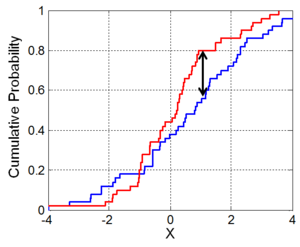

The first test will be the one-sample case. We will test whether our sample comes from a normal distribution or not:

[h0, p_value, d, cv] = kstest(normalize(returns), "Alpha", 0.00001) %#ok<*ASGLU> % α significance level set to 0.00001 (the probability of committing a type I error)
[h0,p_value, d, cv] = kstest(normalize(logreturns), "Alpha", 0.00001)

As expected, the null hypothesis for both the returns and log-returns being a realization of the normal distribution is rejected with a p-value virtually equal to 0 (i.e., *the probability of obtaining the test results at least as extreme as the result actually observed, ****under the assumption that the null hypothesis is correct****).*

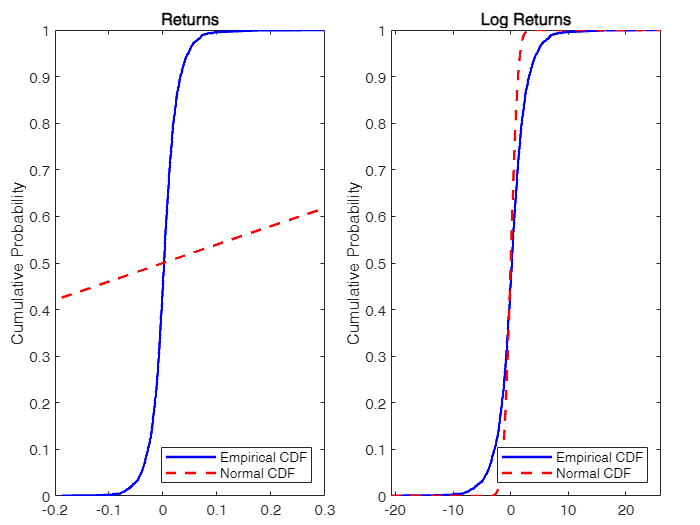

figure;
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

% Plot 1: Returns
nexttile;
sorted_returns = sort(returns);
ecdf_returns = (1:length(sorted_returns)) / length(sorted_returns);
plot(sorted_returns, ecdf_returns, 'b-', 'LineWidth', 1.5);
hold on;
plot(sorted_returns, normcdf(sorted_returns), 'r--', 'LineWidth', 1.5);
legend('Empirical CDF', 'Normal CDF', 'Location', 'southeast');
hold off;
title('Returns');
ylabel('Cumulative Probability');

% Plot 2: Log Returns
nexttile;
sorted_logreturns = sort(logreturns);

ecdf_logreturns = (1:length(sorted_logreturns)) / length(sorted_logreturns);
plot(sorted_logreturns, ecdf_logreturns, 'b-', 'LineWidth', 1.5);
hold on;

h = logical
   1


d = 0

p = 0.5182

plot(sorted_logreturns, normcdf(sorted_logreturns), 'r--', 'LineWidth', 1.5);
legend('Empirical CDF', 'Normal CDF', 'Location', 'southeast');
hold off;
title('Log Returns');
ylabel('Cumulative Probability');
gcf.Position(3:4) = [800 400];  % Width and height of the figure in pixels

In the second test, the two-sample case, we will test the H0 that the log-returns and the simple returns are realizations of the same theoretical distribution:

[h, d, p] = kstest2(returns, logreturns, "Alpha" , 0.0001)

h = logical
   1


p_value = 5.0000e-04

adstat = Inf

cv = 0.7517

Again, the test strongly rejects the H0, suggesting the samples come from different distributions.

#### Anderson-Darling

One practical downside of the Kolmogorov-Smirnov test is its sensitivity to outliers, due to the test statistics itself (greatest distance of the differences), even though it has a strong mathematical-statistical underlying concept (the [Glivenko-Cantelli Theorem](https://en.wikipedia.org/wiki/Glivenko%E2%80%93Cantelli_theorem)). The Anderson-Darling test has the a similar underlying logic (it has a EDF statistic) and is a specific case of the *Cramer-von Mises Test.*


$$A^2 = n\int_{-\infty}^{\infty} [F_n(x)-F(x)]^2w(x)dF(x) \\ w(x) = [F(x)(1-F(x))]^{-1}$$


Thanks to the specific weight w(x), $A^2$ places more weights on tails' observations

[h, p_value, adstat, cv] = adtest(returns)

h = logical
   1


p_value = 5.0000e-04

adstat = Inf

cv = 0.7517

[h, p_value, adstat, cv] = adtest(logreturns)

#### Shapiro-Wilk

This test takes a different approach, with a statistic more difficult to interpret. Essentially, it compares the *order statistics *of the normal distribution with the our sample ones. 


$$W = \frac{\bigg(\sum_{i=1}^na_ix_{(i)}\bigg)^2 }{\sum_{i=1}^n(x_i - \bar{x})^2}$$



$$(a1, \dots, a_n) = \frac{m^T V^{-1}} {C}$$



$$C = ||V^{-1}m|| = \sqrt{(m^TV^{-1}V^{-1}m)} \\
m = (m_1, \dots, m_n)^T
$$


C is the vector norm.

% This test is not avaiable in the Statistics and Machine Learning Toolbox, so it must be downloaded from file-exchange. External files can be added from Add-Ons ribbon.
% To permit ease of use, a specific function is made to download and
% install the package

function installFileExchangePackage(submissionID)

Unzipping submission 13964...
Adding submission 13964 to MATLAB path...
Submission 13964 installed successfully.


                  % generic link for downloads
                  %                                                                                                     ID for specific file

 swtest Shapiro-Wilk parametric hypothesis test of composite normality.
    [H, pValue, SWstatistic] = swtest(X, ALPHA, TAIL) performs
    the Shapiro-Wilk test to determine if the null hypothesis of
    composite normality is a reasonable assumption regarding the
    population distribution of a random sample X. The desired significance 
    level, ALPHA, is an optional scalar input (default = 0.05).
    TAIL indicates the type of test (default = 1).
 
    The Shapiro-Wilk hypotheses are: 
    Null Hypothesis:        X is normal with unspecified mean and variance.
       For TAIL =  0 (2-sided test), alternative: X is not normal.
       For TAIL =  1 (1-sided test), alternative: X is upper the normal.
       For TAIL = -1 (1-sided test), alternative: X is lower the normal.
 
    This is an omnibus test, and is generally considered relatively
    powerful against a variety of alternatives.
    Shapiro-Wilk test is better than the Shapiro-Francia test f

    url = sprintf('https://www.mathworks.com/matlabcentral/mlc-downloads/downloads/submissions/%d/versions/1/download/zip', submissionID);

h = logical
   1


p_value = 0

swstat = 0.9154

h = logical
   1


p_value = 0

swstat = 0.9230

    % define temp file path to save the downloaded zip file
    tempZipFilePath = fullfile(tempdir, sprintf('submission_%d.zip', submissionID));
    
    % define temp folderpath to unzip the file

h = 1

p_value = 1.0000e-03

lstat = 0.0778

cv = 0.0168

    tempUnzipFolderPath = fullfile(tempdir, sprintf('submission_%d', submissionID));

h = 1

p_value = 1.0000e-03

lstat = 0.0757

cv = 0.0168

    
    % download zip file
    fprintf('Downloading submission %d...\n', submissionID);
    websave(tempZipFilePath, url);
    
    % unzip the file

h = 1

p_value = 1.0000e-03

jbstat = 1.2829e+04

cv = 5.9728

    fprintf('Unzipping submission %d...\n', submissionID);

h = 1

p_value = 1.0000e-03

jbstat = 8.6267e+03

cv = 5.9728

    unzip(tempZipFilePath, tempUnzipFolderPath);
    
    % add the unzipped folder to the MATLAB path
    fprintf('Adding submission %d to MATLAB path...\n', submissionID);
    addpath(tempUnzipFolderPath);
    
    % save the path for future MATLAB sessions
    savepath;
    
    % delete  temp zip file
    delete(tempZipFilePath);
    
    fprintf('Submission %d installed successfully.\n', submissionID);
end

.

installFileExchangePackage(13964);

q = logical
   1


p_value = 4.6481e-06

c_value = 39.1309

help swtest % we now have the swtest that can be used for testing
[h, p_value, swstat] = swtest(returns)
[h, p_value, swstat] = swtest(logreturns)

#### Lilliefors

This test is essentially the same as the Kolmogorov-Smirnov test, with the same test statistics (greatest distance between the CDFs). While the KS-test is completely agnostic to the underlying distriburtion, the Lilliefors adds an assumption with the *estimates of *the mean and variance of the sample. This is why it is also called "Lilliefors c*orrected KS test*". It is more powerful than the KS version (*i.e.*, correctly reject the H0 of normal distribution more often).

[h, p_value, lstat, cv] = lillietest(returns)
[h, p_value, lstat, cv] = lillietest(logreturns)

#### Jarque-Bera

This last test is different than the other ones. This test compares the sample skewness and kurtosis to the normal distribution. As we know, the normal distribution skewness and -excess- kurtosis are equal to zero. Technically, the H0 of the JB-test is a *joint *hypothesis of $S = 0 \cup K-3 = 0$.


$$JB = \frac{n}{6}\bigg(\hat{S}^2 + \frac{1}{4}(\hat{K} - 3)^2\bigg) \\
\hat{S} = \text{sample skewness}\\ \hat{K}\text{ = sample kurtosis}$$


[h, p_value, jbstat, cv] = jbtest(returns)
[h, p_value, jbstat, cv] = jbtest(logreturns)

In this large sample context, the empirical distributional convergence is ... , leading to the detection of even trivial departures from the null distribution. In these cases, more importance is given to the **effect size** than the actual test significance.

### Some annotations on financial markets theory

Generally, the evolution of stock returns$\{r_t\}$can be defined as a *joint distribution*:


$$F(r_{i1}, \dots, _{iT}; \theta) = F(r_{i1})\prod^T_{t=2}F(r_{it}|r_{i,t-1}, \dots, r_{i1})$$


This formualtion highlights the temporal dependencies of the (log) returns $r_{it}$.

In financial theory, there are different theories relying on different formulations and hypotheses. One of the most common is the *random walk hypothesis. *One version of it is that the conditional distribution $F(r_{it}|r_{i,t-1}, \dots, r_{i1})$ is equal to the marginal distribution $F(r_{i1})$. In this case, returns are temporally independent and, hence, not predictable. The random walk hypothesis is strictly related to the **efficient market hypothesis**, which says that asset prices reflect all available information, hence arbitrage-free.

This well-supported theory, particularly in high-volume/liquid markets and over the medium to long term, suggests that asset returns are very unlikely to exhibit significant trends, seasonality, or serial correlation. These aspects might be more interesting to be analyzed in the *prices *time series.

Another important aspect of returns is their *loss/gain asimmetry, *a phenomenon where positive total returns in financial markets take a longer time to accrue compared to negative returns. In simpler terms, losses tend to happen faster and more intensely than gains.

To sum up, *stylized empirical facts* from the "*Empirical properties of asset returns: stylized facts and statistical issues*" paper by R Cont are reported:

- **Absence of autocorrelations**: (linear) autocorrelations of asset returns are often insignificant, except for very small intraday time scales (around 20 minutes) for which microstructure effects come into play.

- **Heavy tails**: the (unconditional) distribution of returns seems to display a power-law or Pareto-like tail, with a tail index which is finite, higher than two and less than five for most data sets studied. In particular this excludes stable laws with infinite variance and the normal distribution. However the precise form of the tails is difficult to determine.

- **Gain/loss asymmetry**: one observes large drawdowns in stock prices and stock index values but not equally large upward movements.

- **Aggregational Gaussianity**: as one increases the time scale Δt (from days to weeks, for examples) over which returns are calculated, their distribution looks more and more like a normal distribution. In particular, the shape of the distribution is not the same at different time scales.

- **Volatility clustering**: different measures of volatility display a positive autocorrelation over several days, which quantifies the fact that high-volatility events tend to cluster in time.

- **Conditional heavy tails**: even after correcting returns for volatility clustering (e.g. via GARCH-type models), the residual time series still exhibit heavy tails. However, the tails are less heavy than in the unconditional distribution of returns.

- **Slow decay of autocorrelation in absolute returns**: the autocorrelation function of absolute returns decays slowly as a function of the time lag, roughly as a power law with an exponent β ∈ [0.2, 0.4]. This is sometimes interpreted as a sign of long-range dependence.

- **Leverage effect**: most measures of volatility of an asset are negatively correlated with the returns of that asset.

- **Volume/volatility correlation**: trading volume is correlated with all measures of volatility.

- **Asymmetry in time scales**: coarse-grained measures of volatility predict fine-scale volatility better than the other way round.

Obviously, these can give us some *priors* to be tested and eventually updated for our context of analysis.

## Time Series Analysis: Frameworks, Instruments and Theory

Linear time series analysis provides a natural framework to study the dynamic structure of a time series. The main underlying theories are: 

- stationarity;

- dynamic dependence;

- (partial) autocorrelation function;

- modelling;

- forecasting.

Instead, the main econometric models are:

- autoregressive (AR) models;

- moving-average (MA) models;

- mixed autoregressive moving-average (ARMA) models;

- seasonal models;

- unit-root non-stationarity;

- regression models with time series errors;

- fractionally differenced models for long-range dependence.

*Time Series Analysis; Forecasting and Control *by Box-Jenkins (1970) may be considered as The Bible of time series modelling, because it gives a thorough methodological approach towards the "best" model estimation.

They proposed an *iterative three-stage modeling approach, *detailed below:

- **model identification and selection**;

- **parameter estimation **(*model fitting*);

- **statistical model checking **(*diagnostics*).

A pipeline is defined:

`TS > Identification Tests > Specification > Estimation > Diagnostic Checking > Analysis and Forecasting`

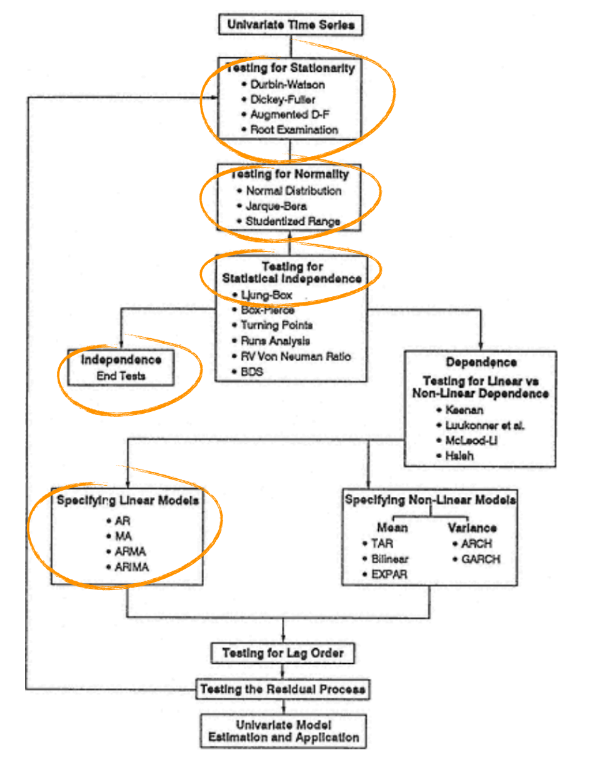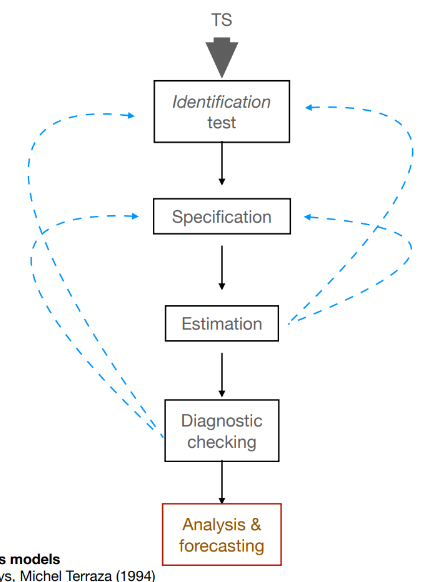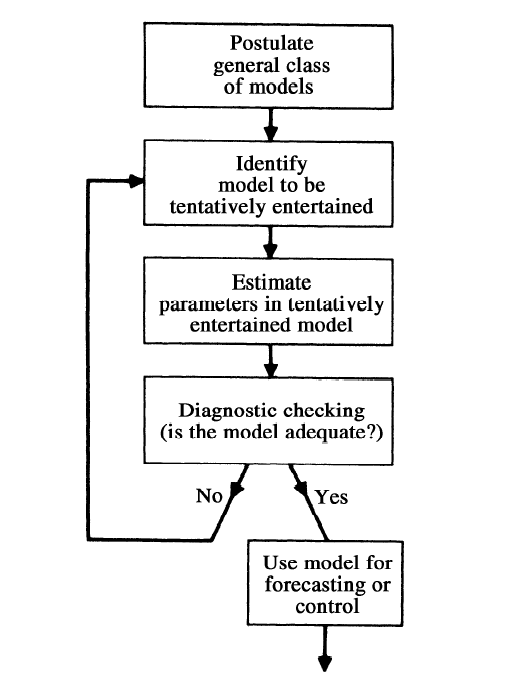

It is important to know that either diagnostic checking and estimation may lead again to the identification tests and specification steps in order to iteratively find the best parameters that best fits the data.

Also, the model must have the characteristic of *parsimony *(Tukey 1961) and its selection must start from a well-defined interaction of theory and pratice, in order to consider a *useful class of models *for our purposes.

- Look for any *trend/stationarity* by plotting the time series;

- use to log to reduce the trend and eventually *differentiate* to eliminate the seasonality;

- examine the *ACF/PACF plots *of the differentiated time series and choose the order of the model to estimate from there;

- fit the hypothesized model to data;

- study the *residuals *of the fit to check whether and how the model is correct, by looking at the ACF/PACF plots;

- use the fitted models to make *forecasting *estimates.

Again, this has to be do in an *iterative way.*

### **Stationarity**

The foundation of time series analysis is stationarity. It can be either *strict *or *weak. *Strict stationarity happens when the joint distribution of $(r_{t_1}, \dots, r_{t_k})$ = $(r_{{t_1}+t}, \dots, r_{{t_k}+t}) \space \forall t,$ where *k* is an arbitrary positive integer and $(t_1, \dots, t_k)$ is a collection of *k *positive integers. So strict stationarity requires that the joint distribution of $(r_{t_1}, \dots, r_{t_k})$ is *invariant *under time shifts.

Weak stationarity (also called covariance stationarity), instead, is a more flexible version, requiring constant mean $E(r_t) = \mu$, constant variance $Var(r_t) = 0$ and covariance only depending on time difference $Cov(r_t, r_{t-k}) = \rho_k $, this term defined as the lag-ρ autocovariance of $r_t$. The weak stationarity is a common assumption (always to be tested) in the financial literature for returns.

In a regression context, econometricians usually look - other than *absence of collinearity *and *error orthogonality -* for stationarity in order to have *consistent *estimates of the parameters, because it simplies statements of the LLN and the CLT.

It is important not to confuse the lack of stationarity (presence of unit-root) with* trend*. 

It might appear convinient to apply to always differentiate the time series; this is essentially wrong and could lead to *overdifferentiation*, making the model more complicate and leading to a *nonivertible *model, which leads to inconsistency in model estimations.

### Autocorrelation and Partial Autocorrelation Function

The autocorrelation and partial autocorrelation functions `a`re useful devices for describing the behaviour of stationary processes.

Given covariance-stationarity, correlation coefficient between $r_t$ and $r_{t-k}
$ is only a function of *k.* The correlation coefficient is then called lag-*k autocorrelation.*


$$0< \rho_k = \frac{Cov(r_t, r_{t-k})}{\sqrt{Var(r_t)Var(r_{t-k})}} = \frac{Cov(r_t, r_{t-k})}{Var(r_t)} = \frac{\gamma_k}{\gamma_0} < 1
$$


Obviously, this is a population parameter, to be consistently estimated under some general conditions with $\hat{p}_k$. A satisfactory estimate of the *k-*th lag autocorrelation $\rho_k$ is:


$$\hat{\rho_k} = \frac{c_k}{c_0}  \\
c_k = \frac{1}{N} \sum^{N-k}_{t=1} (z_t - \bar{z}) (z_{t+k} - \bar{z}) \\
c_0 = \frac{1}{N} \sum_{t=1}^{N}(z_t - \bar{z})^2$$


Practically correct autocorrelation estimates would be calculated with at least 50 observations and K not larger than N/4.

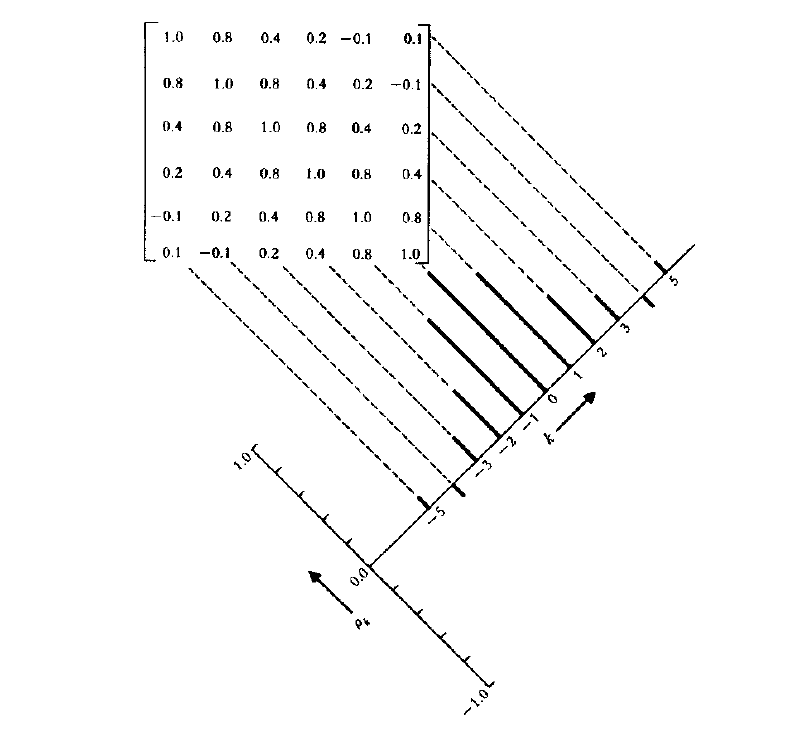

To identify a model for times, it is essential to have a rough check on whether the autocorrelation value is statistically beyond 0 at a certain lag. Obviously, to do this, the variance of the ACF must be estimated. The approximate variance of a stationarity normal process is given by:


$$var[r_k] \simeq \sum^\infty_{v=-\infty} (\rho^2_v + \rho_{v+k} \rho_{v-k}- 4\rho_{k}\rho_{v}\rho_{v+k} + 1\rho^2_{v}\rho^2_{k})$$


### **Basic models: autoregressive and moving-average model**

A moving average (MA) model is essentially a weighted aveage of k adjacent past errors. The following model is a *MA of order q*:


$$y_t = \alpha + e_t + \theta_1 e_{t-1} + \theta_2 e_{t-2} + \dots + \theta_q + \theta e_{t-q}$$


with the error considered as a *white noise. *The theoretical properties of a MA(q) model are:

- 
$$E(y_t) = \alpha$$


- 
$$Var(y_t) = \sigma^2_w\left(1 + \sum_{j=1}^q\theta^2_j\right)^{-1}
$$


- 
$$Corr(y_t) = \rho_k = \theta_k + \sum_{j=1}^{q-k}\theta_j \theta_{j+k} \cdot \left( 1 + \sum_{j=1}^q \theta^2_j \right)^{-1}$$


For either MA and AR, the first two or three orders are of practical importance.

#### Moving-Average

#### Auto-regressive

To formally assess the lack of global autocorrelation, we can make use of the **Portmanteau test**, developed by Box and Pierce in 1970. It is a multiple hypothesis test, so it has the same testing logic of the F-test.


$$H_0 : \rho_1 = \rho_2 = \dots = \rho_k = 0\\ H_1: \exists \rho \neq0$$


The statistic is:


$$Q^*(m)= T \sum^m_{k=1}\hat\rho^2_k
$$


Under the null hypothesis, the statistic test is asymptotically distributed as a $\chi^2 (m)$ distribution. The original test is not available on MATLAB.

The **Ljung-Box test **(1978) is a modification of the Portmanteau, in order to increase its power in finite samples (in our case it is almost irrelevant). The modified test statistic is:


$$Q(m) = T(T+2) \sum_{k = 1}^m \frac{\hat{\rho}^2_k}{T-k}$$


The decision rule is to reject H0 if $Q(m) > \chi_\alpha^2 $. m can be considered as a *hyperparameter*, usually chosen at `ln(T)` (Tsay) or `min(20, T-1)` (Box-Jekins-Riesnel-Ljung). In any case, we perform the test for 1:20 lags, tabulating the p-values.

[q, p_value, c_value] = lbqtest(logreturns, Lags = ceil(log(length(logreturns))))

results_table = 20×2 table
    # of Lags    LB P-value
    _________    __________

        1         0.0011474
        2          0.003121
        3         0.0091205
        4          0.020489
        5          0.023944
        6           0.01274
        7        8.4163e-05
        8        4.6481e-06
        9        3.1126e-06
       10        3.9941e-06
       11        8.3898e-06
       12        1.1095e-05
       13        1.5237e-05
       14        1.3489e-05
       15        6.2114e-06
       16        2.8054e-06


num_lags = (1:20)';
p_values_lb = zeros(20, 1);


for lag = 1:20
    % Loop through lags from 1 to 10 and perform the LB test
    [~, p_value_lb_log] = lbqtest(logreturns, 'Lags', lag);
    p_values_lb(lag) = p_value_lb;
end

results_table = table(num_lags, p_values_lb, ...
                      'VariableNames', {'# of Lags', 'LB p-value'});

% Display the table
(results_table)

As shown, for every choice of lag the H0 is rejected at least at a 5% significance level.

[*Some doubts about the asymptotical behaviour of the Ljung-Box Statistic*](https://stats.stackexchange.com/questions/6455/how-many-lags-to-use-in-the-ljung-box-test-of-a-time-series)

## Box-Jenkins

Identification methods are rough procedures applied to a set of data to indicate the kind of model that is worthy of further investigation. Box and Jenkins, in their book, say that *"given that at identification stage no precise formulation of the problem is available, statistically "inefficient" methods must be necessarily used". *This used to be obvious in the period when they published the first edition of the book (1970), due to computational limits and hence lack of general algorithms such as *forecast::auto-arima* on R, where identification methods could be skipped altogether. Nonetheless, we follow the Box-Jenkins pipeline in order to understand how it *works *and be more conscious about the results. 

The stages in the identification procedures in order to select a subset of models from the general ARIMA are:

- assess stationarity of the process and eventually differentiate it in order to produce stationarity;

- identify the resulting autoregressive-moving average (ARMA) model for $y_t$.

The principal identification tools will be the autocorrelation and partial autocorrelation functions, representable with *auto-correlograms. *It's important to know that, other than helping to know the form of the model, they are also useful to obtain approximate estimates of the parameters. Such approximations are often useful at the estimation stage to provide starting values for iterative procedures employed at that stage.

The **auto-correlogram **is the graphical device used to visually assess the degree of autocorrelation and partial autocorrelation for different lags. They are the main tools for identification inquiry.

 The ACF correlogram is plotted for either *returns *and *log-returns:*

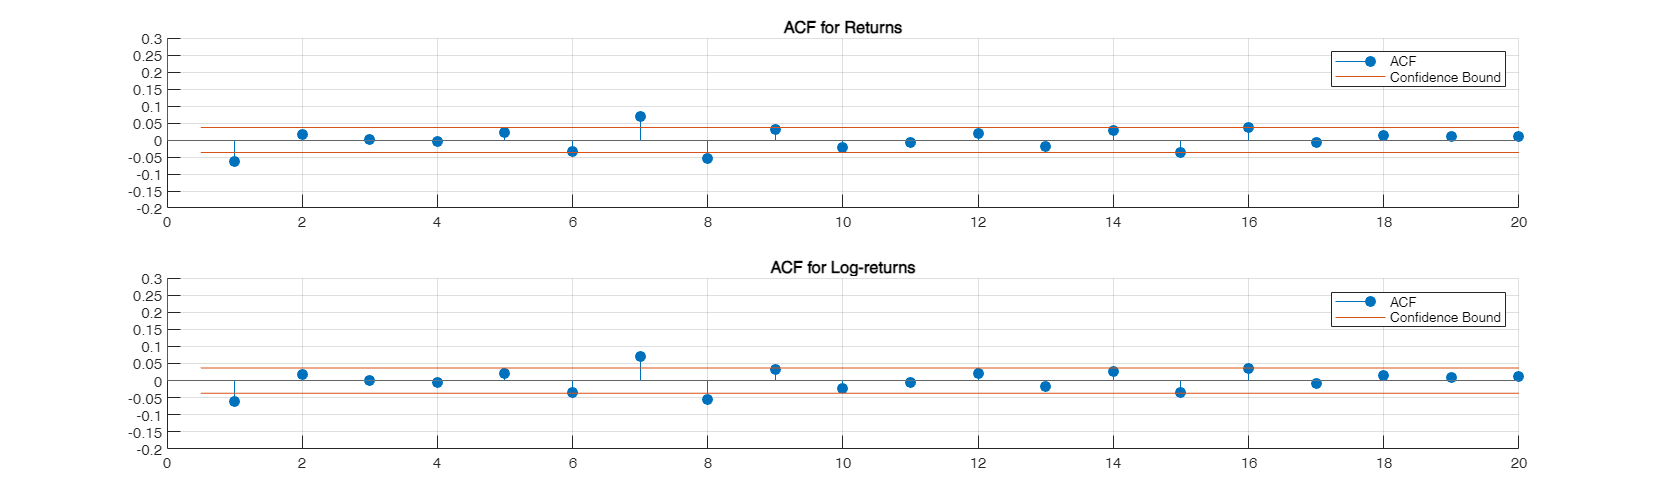

figure
tiledlayout(2,1);

% Tile 1
nexttile
autocorr(returns)
title("ACF for Returns")
ylabel(""); xlabel("")
ylim([-0.2, 0.3]) %% I have cut the ACF plot to visualize better the values
set(gcf, 'position', [10, 10, 2000, 600]);
box off

% Tile 1
nexttile
autocorr(logreturns)

title("ACF for Log-returns")
ylim([-0.2, 0.3])
ylabel(""); xlabel("")
set(gcf, 'position', [10, 10, 2000, 600]);
box off

As shown, both times series present no substantial autocorrelation. The 7th lag may lead to think there might be a weak and weekly pattern, but this observation is wrong, due to the trading days problem (absence of saturdays and sundays). It is commonly said that a series is stationary if the auto-correlogram values damp out to and around zero very fast. Later the presence of stationarity will be formally assessed with proper statistical tests.

The *partial autocorrelation *is a function of its ACF and is a tool for determining the order *p *of an AR model. To understand the PACF consider the following AR models:

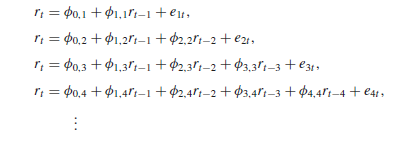

$\phi_{2,2}$ shows the added contribution of $r_{t-2} $ to $r_t$ over the AR(1) $r_t = \phi_0 + \phi_1 r_{t-1} + e_{1t}$

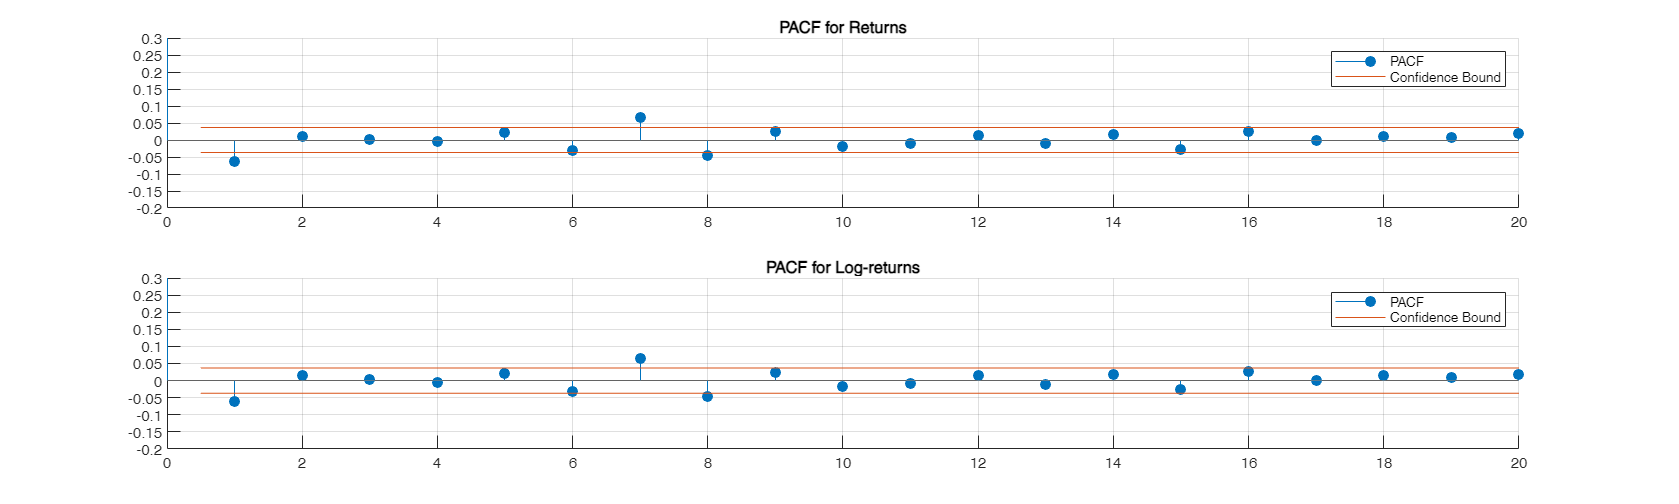

figure
tiledlayout(2,1);

% Tile 1
nexttile
parcorr(returns)
title("PACF for Returns")
ylabel(""); xlabel("")
ylim([-0.2, 0.3])  %% cut the PACF to visualize better the values
set(gcf, 'position', [10, 10, 2000, 600]);
box off

% Tile 1
nexttile
parcorr(logreturns)
title("PACF for Log-returns")
ylabel(""); xlabel("")
ylim([-0.2, 0.3])
set(gcf, 'position', [10, 10, 2000, 600]);
box off

Also in this case, both times series present no substantial partial autocorrelation, thus leading to hypothesize the series to be white noise one.

The ACF and the PACF are the main tools for understanding the MA and AR orders respectively, specified later.

### Unit Root Analysis

Searching for the presence of a **unit-root **is the first step when it comes to analyzing a time series. The simplest example is with an AR(1) model:


$$y_t = \alpha + \rho y_{t-1} + e_t$$


where $e_t
$ is the *innovation*, assumed to be i.i.d. with mean 0 and independent on its own past values (*martingale difference sequence*). The time series is a **random walk **if $\rho = 1$ without or with *drift* α.

A random walk, and in general unit-root time series, are neither strict nor covariance stationary. To see why, consider taking the variance by repeatedly substituting the y's with the innovation term:


$$Var(y_t) = Var(e_t) + Var(e_{t-1}) + \dots + Var(e_1) = \sigma^2_e t$$


The variance *depends *on t, hence the weak stationarity assumption of constant variance is violated. Another key characteristic of unit-root processes is their high persistance in time, meaning a high correlation even between two very distant y values.

 Unit-root processes are also said to be **integrated of order 1**, and I(1) are said to be **difference-stationary**, meaning they can be transformed to stationary series by differencing the values. 


$$\Delta y_t = y_t - y_{t-1} = e_t$$


Practically, shocks in unit-root processes have *permanent effects*. This is the reason why it is especially important in policy-making (especially for macroeconometricians). Instead, shocks in stationary time series have *transitory effects*, with the series considered as *mean-reverting*.

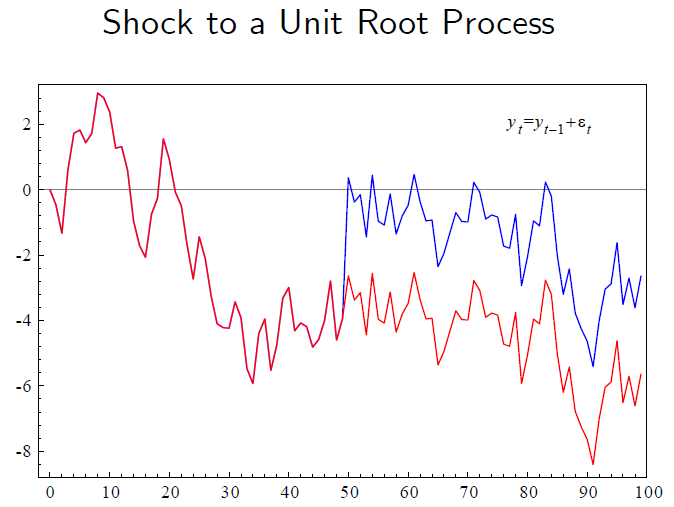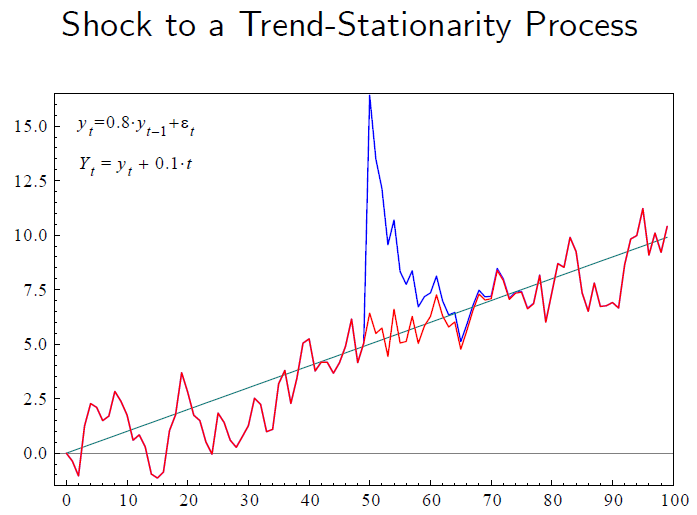

To assess the presence of unit roots, we make use of the sample autocorrelations as consistent estimators of the respective population parameters, along with formal statistical tests.

The performed tests will be:

- (Augmented) Dickey-Fuller (1979)

- Phillips-Perron Tests (1988)

- Variance-Ratio Test (1988)

- Kwiatkowski–Phillips–Schmidt–Shin (1992)

#### (Augmented) Dickey Fuller (ADF)

This is the most famous test for the presence of unit root.


$$H_0: \rho = 1\\ H_1 : \rho< 1 $$


If the H0 is rejected, the process is said to be stable, weakly dependent or asymptotically uncorrelated ($E[y_t, y_{t+h}] = \rho^h \rightarrow 0$).

The test works either with or without a constant term (called *drift*).

The considered equation for the test is the following:


$$\Delta y_t = \alpha + \theta y_{t-1} + e_t$$


Given that, under H0, $y_{t-1}$ is I(1), the CLT that underlies the asymptotic standard normal distribution for the t-statistic does not apply. For this reason, another asymptotic distribution is considered, called the **Dickey-Fuller distribution**, leading to the formulation of new critical values, so the usual t-statistic $\hat{\tau} =  \frac{\hat{\theta}-1}{se(\hat{\theta})}$ can be used.

[h,p_value, stat, c_value, reg] = adftest(returns, 'lags', 0:5)

Error: File: adftest.m Line: 1364 Column: 4
All functions in a script must be closed with an 'end'.

[h, p_value, stat, c_value, reg] = adftest(logreturns, 'lags', 0:5)

As expected, the returns time series present weak stationarity, so it is a I(0) series. It is important to remind that the series is already practically differenced from the prices series.

The test can be extended for trend-stationary processes, which can be mistaken for a unit root process if we do not control for a time trend $\delta$ or constant $\alpha$ in the Dickey-Fuller regression. Carrying the usual DF test without account for the trend we will have less power for rejecting a unit root. 


$$\Delta y_t = \alpha + \delta t + \theta y_{t-1} + e_t$$


The table below shows the critical values when a linear trend is hypothesized.

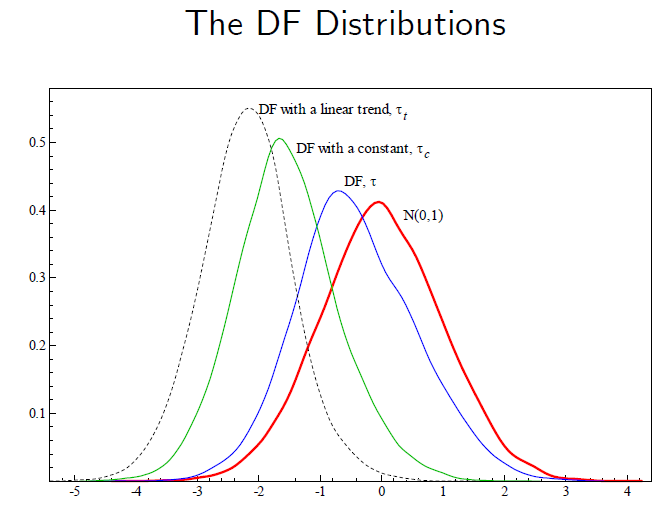

The **augmented **version of the Dickey-Fuller adds lagged differences of our current observation in order to remove eventual correlation in the residuals.


$$\Delta y_t = \alpha + \delta t + \theta y_{t-1} + \sum_{i=1}^{p} \phi_i \Delta y_{t-i} + e_t$$


gls

h = logical
   1


p_value = 1.0000e-03

stat = -56.9514

c_value = -1.9416

h = logical
   1


p_value = 3.8625e-32

stat = -11.8009

c_value = 1.9600

%%econometricModeler()

#### Phillips-Perron (PP)

An alternative to the ADF test is the Phillips-Perron test, a non-parametric correction based on *HAC (Newey-West) standard errors*. It doesn't explicitly model the serial correlation/skedastic function (as ADF-GLS does) but instead relies on a non-parametric correction to the t-statistic used in the test. This correction makes the test more robust to potential serial correlation in the residuals.

[h,p_value,stat,c_value] = pptest(returns)

h = logical
   0


p_value = 0.1000

stat = 0.0785

c_value = 0.1460

#### **Kwiatkowski–Phillips–Schmidt–Shin (KPSS)**

Contrary to the DF test, this test has **stationarity as null hypothesis**. This testing design permit include the *trend-stationarity* in the hypothesis by default. This is an important distinction since it is possible for a time series to be non-stationary, have no unit-root yet to be trend-stationary.


$$KPSS  = \frac{1}{T^2} \frac{\sum_{t=1}^T S^2_t}{\hat{\sigma}_\infty^2} \\
S_t = \sum^t_{s=1} \hat{e}_s \\
\hat{\sigma}^2_\infty: \text{HAC estimator of residuals variance} $$


HAC stands for *Heteroskedastic-autocorrelation consistent.*

[h,p_value,stat,c_value] = kpsstest(returns)

h = logical
   0


p_value = 0.1000

stat = 0.0843

c_value = 0.1460

reg = struct with fields:
        num: 2914
       size: 2914
      names: {2×1 cell}
      coeff: [2×1 double]
         se: [2×1 double]
        Cov: [2×2 double]
     tStats: [1×1 struct]
      FStat: [1×1 struct]
        yMu: 0.2117
     ySigma: 2.8023
       yHat: [2914×1 double]
        res: [2914×1 double]
    autoCov: 7.8477
      NWEst: 7.8477
     DWStat: 2.1202
        SSR: 6.6424
        SSE: 2.2868e+04
        SST: 2.2875e+04
        MSE: 7.8531
       RMSE: 2.8023
        RSq: 2.9038e-04
       aRSq: -5.2930e-05
         LL: -7.1365e+03
        AIC: 1.4277e+04
        BIC: 1.4289e+04
        HQC: 1.4281e+04


[h,p_value,stat,c_value, reg] = kpsstest(logreturns)

#### How to test? A student-Friendly Testing Strategy

by John Elder and Peter E. Kennedy.

All these tests and their different parametrizations may be confusing. Automatizing the process is a bad way to perform stationarity tests. The two authors suggest to simply "*exploit prior knowledge of the growth status of the time series", *thus defining a proper *testing strategy*.

Most textbooks begin by estimating the equation:


$$y_t = \rho y_{t-1} + \alpha + \beta t + \epsilon_t \\ \Delta y_t = (\rho - 1)y_{t-1} + \alpha + \beta_t + \epsilon_t$$


testing for $\rho$ = 1 *while *worrying about whether $\alpha$ and $\beta$ are zero or not.

- "*They do not exploit prior knowledge of the growth status of th variable under test, forcing their strategies to cover all possibilities. For example, unemployment clearly does not have a long-run growth trend, unit-root testing should begin by setting the trend coefficient *$\beta$* = 0 unless a plot of the data reveals an apparent trend during the time period covered by the data*"

- "*They worry about outcomes that are not realistic. For example, consider the case of *$\rho = 0, \space \beta \neq 0$*, thought to be unrealistic for economic time series because it implies an ever increasing (or decreasing) rate of change. Unit root tests are known for their low power, thus leading to higher chances of committing a type II error*".

- *They double- and triple-test for *$\rho$* = 1 as their testing strategies proceed, 3 presumably to alleviate the low power of unit-root tests. Although this may have some merit, it flirts with *[***pretest bias***](https://davegiles.blogspot.com/2016/05/a-quick-illustration-of-pre-testing-bias.html)*, and, of more importance, complicates the strategy for students as well as practitioners.* 

### ARMA Identification

In some applications, the AR or MA models discussed in the previous sections become cumbersome because one may need a high-order model with many parameters to adequately describe the dynamic structure of the data. To overcome this difficulty, the autoregressive moving-average (ARMA) models are introduced;


$$\text{ARMA} : y_t = \rho_1 y_{t-1} + \dots + \rho_{p} y_{t-p} + a_t - \theta_1e_{t-1} - \dots -\theta_q e_{t-q} + e_t \\
\quad \quad \quad \enspace \rho(B^p)y_t = \theta(B^q)a  \quad (\text{Lag operator notation})$$


the term $e_t$ is the **white noise**, a sequence of uncorrelated random varaibles with mean zero ($E[a_t] = 0$) and constant variance ($var[a_t] = \sigma_a^2$)

The current value is systematically explained both by it's previous values and errors (innovations). The combination of these two permits to have a parsimonious parametrization.

An example is the ARMA(1,1) process:


$$y_t = \overbrace{\rho y_{t-1}}^\text{AR} + e_t - \overbrace{\theta_1 e_{t-1}}^\text{MA}
$$


Already knowing that our series is stationary, no differentiation is needed, hence the I in ARIMA is left out (it would be I(0) ).

Heuristically, the orders and values can be identified by analyzing the ACF for MA and PACF for AR. 

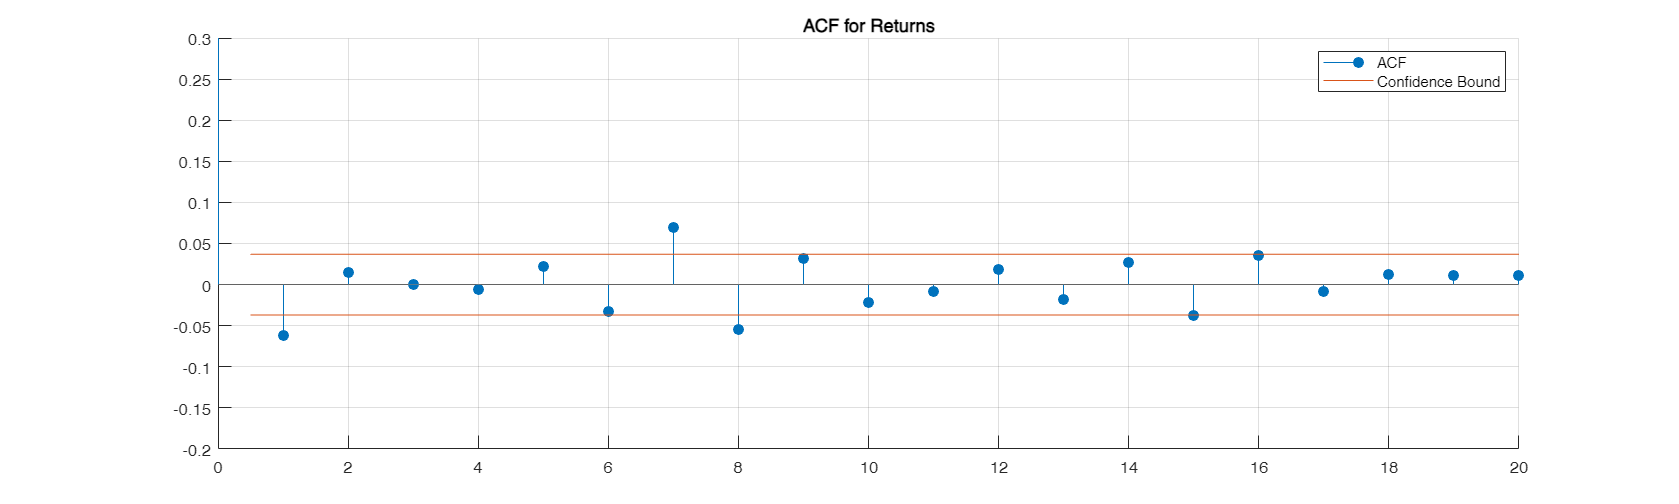

figure
autocorr(returns)
title("ACF for Returns to identify MA order")
ylabel(""); xlabel("")
ylim([-0.2, 0.3])  %% cut the ACF plot to visualize better the values
set(gcf, 'position', [10, 10, 2000, 600]);
box off

As shown in the ACF correlogram, no significant values can be found and every value k > 0 lie around zero. It might be reasonable to include the first one, testing an MA(1) model, even though its estimated value is **0.0662**.

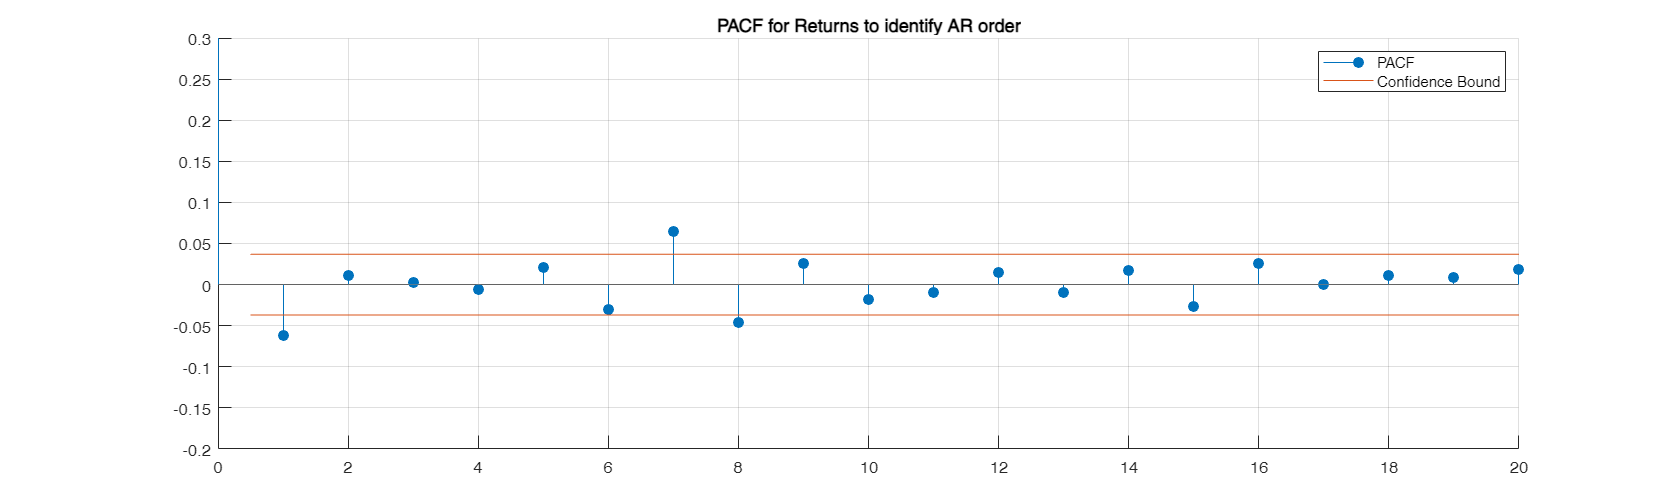

figure
parcorr(returns)
title("PACF for Returns to identify AR order")
ylabel(""); xlabel("")
ylim([-0.2, 0.3])  %% cut the PACF plot to visualize better the values
set(gcf, 'position', [10, 10, 2000, 600]);
box off

Same as PACF for AR, so we try with including only one order, even though it is low as the MA one.

As said before, the two plots strongly hint the series might be a white noise. To check this case, a white noise series is created and plotted:

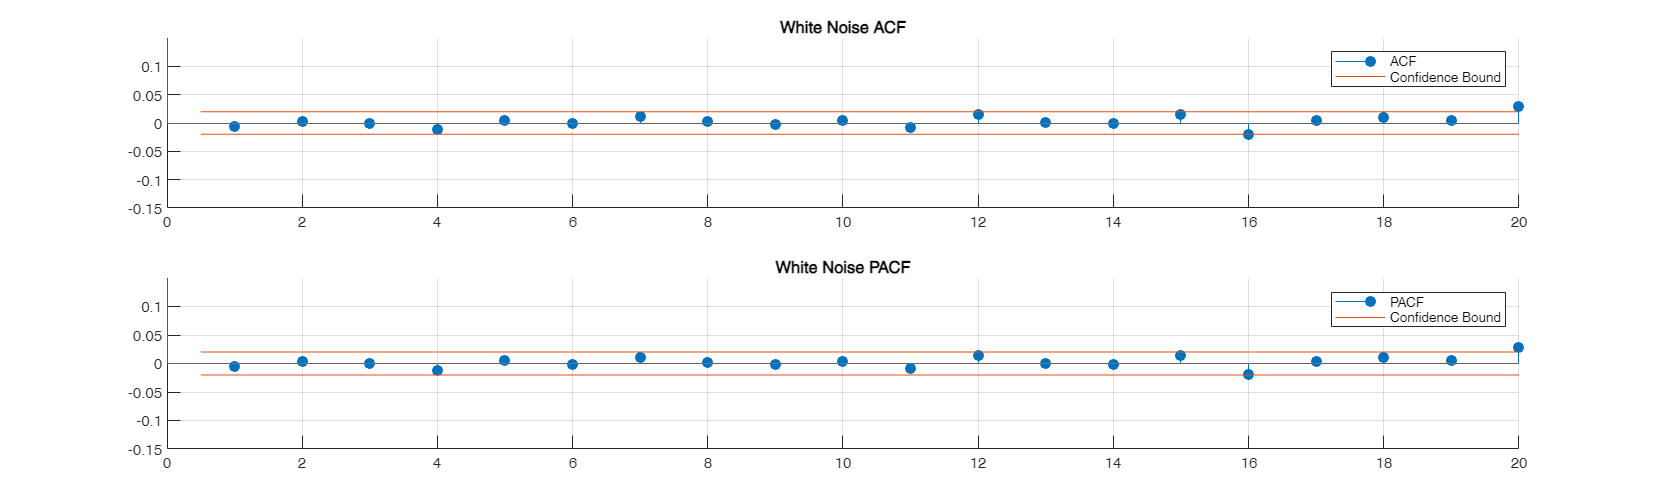

figure
tiledlayout(2,1);
% Tile 1
nexttile

white_noise = randn(10000, 1);
autocorr(white_noise)
ylabel(""); xlabel("")
title("White Noise ACF")
ylim([-0.15, 0.15])  %% cut the ACF plot to visualize better the values
set(gcf, 'position', [10, 10, 2000, 600]);
box off;

% Tile 1
nexttile

parcorr(white_noise)
ylabel(""); xlabel("")
title("White Noise PACF")
ylim([-0.15, 0.15])  %% cut the PACF plot to visualize better the values
set(gcf, 'position', [10, 10, 2000, 600]);
box off;

We check how "robust" the Ljung-Box is by testing a white noise series multiple times:

N = 20;
test_statistic = zeros(N, 1);
p_value = zeros(N, 1);

for iter = 1:N
    white_noise = randn(10000, 1);
    
    [~, p_value(iter), test_statistic(iter)] = lbqtest(white_noise);
end

results_table = table(test_statistic, p_value, ...
    'VariableNames', {'Test_Statistic', 'P_Value'});

(results_table)

results_table = 20×2 table
    Test_Statistic     P_Value 
    ______________    _________

        13.136          0.87148
        13.206          0.86837
        20.254          0.44211
        18.857          0.53116
        18.378           0.5625
        22.021          0.33937
        19.389          0.49668
        40.919        0.0038159
        21.017          0.39611
        21.566           0.3645
        9.9387          0.96927
        15.264          0.76111
        11.435          0.93414
        23.596          0.26048
        25.498          0.18304
        15.678          0.73637


mean(results_table.P_Value)

ans = 0.5490

 `Note``: `from now on the Econometric Modeler is used to perform our tests. It essentially is an application with an intuitive GUI, similar to Gretl.

% econometricModeler

The results can be checked here: [AR(1), MA(1), ARMA(1,1) modelling file](http://../ARMA(1,1)%20-%20AR(1)%20-%20MA(1).html)

Our estimates are essentially not really meaningful, so we won't apply any AR(I)MA model to our data and won't perform forecasting, which will done in the second part. The residuals are the log(returns) values themselves.

`The second part of the analysis is in another Live Script: Volatility Modelling`